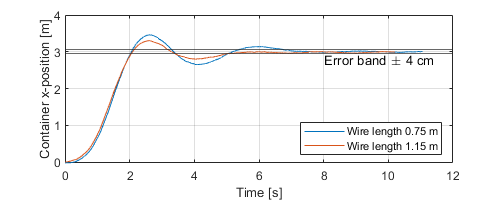

clear all 
close all
clc

x0=0;
y0=0;
plotwidth=500;
height=200;
set(gcf,'position',[x0,y0,plotwidth,height])

A=readmatrix("step3m-2.txt");
s3w15=table((A(:,1)-A(1,1))/1000, A(:,2)-0.5, A(:,3)-0.5, A(:,4), A(:,5), A(:,6), A(:,7),A(:,8), 'VariableNames',{'time','trolleyX','containerX','wireLength','theta','refX','refY','controllerOutput'});

A=readmatrix("step3m-1.15mWire-2.txt");
s3w075=table((A(:,1)-A(1,1))/1000, A(:,2)-0.5, A(:,3)-0.5, A(:,4), A(:,5), A(:,6), A(:,7),A(:,8), 'VariableNames',{'time','trolleyX','containerX','wireLength','theta','refX','refY','controllerOutput'});

plot(s3w075.time, s3w075.containerX,s3w15.time, s3w15.containerX)
xlabel("Time [s]")
ylabel("Container x-position [m]")
yline(2.95)
yline(3.05)
text(8,2.8,"Error band \pm 4 cm")
grid on
legend("Wire length 0.75 m","Wire length 1.15 m","Location","southeast")
exportgraphics(gcf,'longStep.pdf','ContentType','vector')

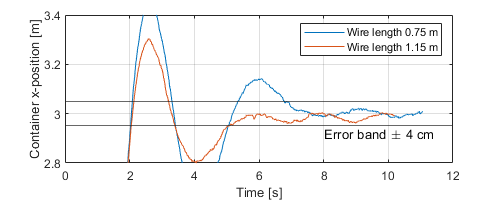


plot(s3w075.time, s3w075.containerX,s3w15.time, s3w15.containerX)
xlabel("Time [s]")
ylabel("Container x-position [m]")
yline(2.95)
yline(3.05)
text(8,2.92,"Error band \pm 4 cm")
grid on
ylim([2.8 3.4])
legend("Wire length 0.75 m","Wire length 1.15 m","Location","northeast")
exportgraphics(gcf,'longStepZoom.pdf','ContentType','vector')

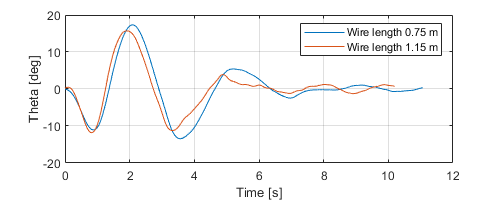


plot(s3w075.time, s3w075.theta,s3w15.time,s3w15.theta)
grid on
ylim([-20 20])
xlabel("Time [s]")
ylabel("Theta [deg]")
legend("Wire length 0.75 m","Wire length 1.15 m","Location","northeast")
exportgraphics(gcf,'longStepTheta.pdf','ContentType','vector')

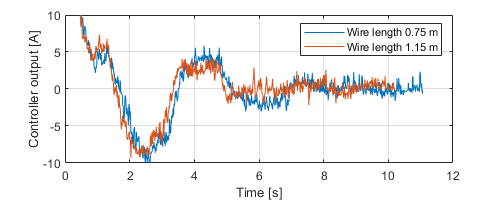

plot(s3w075.time, s3w075.controllerOutput,s3w15.time,s3w15.controllerOutput)
grid on
ylim([-10 10])
xlabel("Time [s]")
ylabel("Controller output [A]")
legend("Wire length 0.75 m","Wire length 1.15 m","Location","northeast")
exportgraphics(gcf,'longStepConOut.pdf','ContentType','vector')

**Korte step**

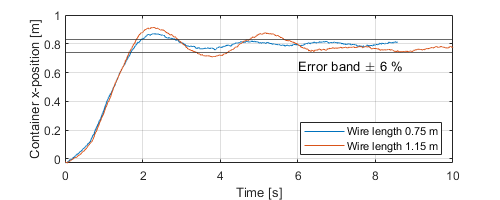

clear all 
close all
clc
x0=0;
y0=0;
plotwidth=500;
height=200;
set(gcf,'position',[x0,y0,plotwidth,height])

A=readmatrix("step0.785m-2.txt");
s078w075=table((A(:,1)-A(1,1))/1000, A(:,2)-0.5, A(:,3)-1, A(:,4), A(:,5), A(:,6), A(:,7),A(:,8), 'VariableNames',{'time','trolleyX','containerX','wireLength','theta','refX','refY','controllerOutput'});

A=readmatrix("LongLineShortStep-8.txt");
s078w115=table((A(:,1)-A(1,1))/1000, A(:,2)-0.5, A(:,3)-1, A(:,4), A(:,5), A(:,6), A(:,7),A(:,8), 'VariableNames',{'time','trolleyX','containerX','wireLength','theta','refX','refY','controllerOutput'});

plot(s078w075.time, s078w075.containerX, s078w115.time, s078w115.containerX)
xlabel("Time [s]")
ylabel("Container x-position [m]")
yline(0.785*1.06)
yline(0.785*0.94)
text(6,0.65,"Error band \pm 6 %")
grid on
legend("Wire length 0.75 m","Wire length 1.15 m","Location","southeast")
xlim([0 10])
exportgraphics(gcf,'shortStep.pdf','ContentType','vector')

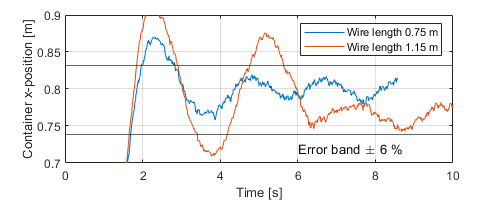


plot(s078w075.time, s078w075.containerX, s078w115.time, s078w115.containerX)
xlabel("Time [s]")
ylabel("Container x-position [m]")
yline(0.785*1.06)
yline(0.785*0.94)
text(6,0.72,"Error band \pm 6 %")
grid on
ylim([0.7 0.9])
legend("Wire length 0.75 m","Wire length 1.15 m","Location","northeast")
xlim([0 10])
exportgraphics(gcf,'shortStepZoom.pdf','ContentType','vector')

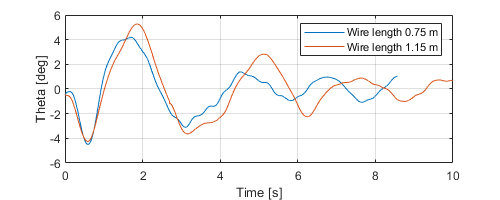


plot(s078w075.time, s078w075.theta,s078w115.time,s078w115.theta)
grid on
ylim([-6 6])
xlabel("Time [s]")
ylabel("Theta [deg]")
legend("Wire length 0.75 m","Wire length 1.15 m","Location","northeast")
xlim([0 10])
exportgraphics(gcf,'shortStepTheta.pdf','ContentType','vector')

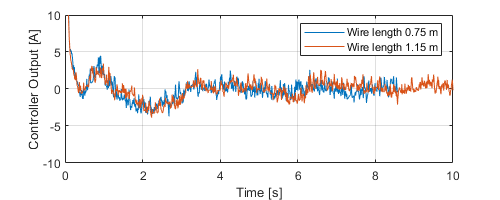


plot(s078w075.time, s078w075.controllerOutput,s078w115.time,s078w115.controllerOutput)
grid on
ylim([-10 10])
xlabel("Time [s]")
ylabel("Controller Output [A]")
legend("Wire length 0.75 m","Wire length 1.15 m","Location","northeast")
xlim([0 10])
exportgraphics(gcf,'shortStepConOut.pdf','ContentType','vector')